% Moment based kalman filter
clear
close all

datasetFolder="./MRCLAM_Dataset1";
robotNumber = "Robot1";
initial_time = seconds(1.248272276e9);

% true data
groundTruthRaw = importdata(strcat(datasetFolder,"/",robotNumber,"_Groundtruth.dat"));
groundTruth=array2timetable(groundTruthRaw.data(:,2:end), ...
    "RowTimes",seconds(groundTruthRaw.data(:,1)), ...
    "VariableNames",{'trueX','trueY','trueTh'});
groundTruth.Time = groundTruth.Time-initial_time;

% observation data 
rng('default');
rng(1);
observationMu = 0;
observationSigma = 0.001;
observationNoise = random('Normal',observationMu,observationSigma,[size(groundTruth,1),3]);
observation = groundTruth{:,:}+observationNoise;
observation = array2timetable(observation, ...
    "RowTimes",groundTruth.Time, ...
    "VariableNames",{'obsX','obsY','obsTh'});
observation.Time = observation.Time-initial_time;

% odometry data
odomRaw = importdata(strcat(datasetFolder,"/",robotNumber,"_Odometry.dat"));
odom = array2timetable(odomRaw.data(:,2:3), ...
    "RowTimes",seconds(odomRaw.data(:,1)), ...
    "VariableNames",{'vel','angVel'});
odom.Time = odom.Time-initial_time;
% dt = seconds(0.01);
% odom = retime(odom,'regular','previous','TimeStep',dt)

% measurement data
measurementRaw = importdata(strcat(datasetFolder,"/",robotNumber,"_Measurement.dat"));
measurement = array2timetable(measurementRaw.data(:,2:4), ...
    "RowTimes",seconds(measurementRaw.data(:,1)), ...
    "VariableNames",{'barcode','range','bearing'});
% measurement.Time = measurement.Time-measurement.Time(1)
landmark_groundTruth = importdata(strcat(datasetFolder,"/","Landmark_Groundtruth.dat"));
landmark_groundTruth = array2table(landmark_groundTruth.data,"VariableNames",{'pole','poleX','poleY','x_std','y_std'})

landmark_groundTruth = 15×5 table
       pole         poleX          poleY         x_std         y_std   
    __________    __________    ___________    __________    __________

    6.0000e+00    5.7093e+00     4.9640e+00    2.7464e-04    4.1465e-04
    7.0000e+00    5.2529e+00     5.5366e+00    1.1889e-04    3.5386e-04
    8.0000e+00    3.6999e+00     4.4664e+00    1.1533e-04    2.1172e-04
    9.0000e+00    2.3145e+00     3.3750e+00    1.1799e-04    1.2106e-04
    1.0000e+01    4.8180e-01     4.3960e+00    1.0721e-04    1.8453e-04
    1.1000e+01    3.1507e+00     2.3829e+00    1.2614e-04    1.3848e-04
    1.2000e+01    4.0633e+00     9.4429e-01    6.1430e-05    1.3376e-04
    1.3000e+01    2.6803e+00     2.6835e-01    9.9390e-05    9.5160e-05
    1.4000e+01    9.4829e-01     7.5601e-01    1.6941e-04    1.5120e-04
    1.5000e+01    3.7629e+00    -2.0309e+00    1.1487e-04    1.7474e-04
    1.6000e+01    1.6984e+00    -2.0897e+00    1.2742e-04    1.4707e-04
    1.7000e+01    3.5962e-02 

barcode = readtable(strcat(datasetFolder,"/","Barcodes.dat"));
barcode = renamevars(barcode,[1,2],{'pole','barcode'});
barcode.pole(11) = 17;
barcode.pole(17) = 11;
measurement = innerjoin(measurement,barcode);
measurement = innerjoin(measurement,landmark_groundTruth);
measurement = sortrows(measurement)

measurement = 4771×8 timetable
        Time          barcode        range         bearing         pole         poleX          poleY         x_std         y_std   
    _____________    __________    __________    ___________    __________    __________    ___________    __________    __________

    1.2483e+09 秒    9.0000e+01    2.1480e+00     2.5000e-02    1.6000e+01    1.6984e+00    -2.0897e+00    1.2742e-04    1.4707e-04
    1.2483e+09 秒    9.0000e+01    2.0330e+00     2.4000e-02    1.6000e+01    1.6984e+00    -2.0897e+00    1.2742e-04    1.4707e-04
    1.2483e+09 秒    9.0000e+01    1.9460e+00     4.0000e-02    1.6000e+01    1.6984e+00    -2.0897e+00    1.2742e-04    1.4707e-04
    1.2483e+09 秒    9.0000e+01    1.8260e+00     4.3000e-02    1.6000e+01    1.6984e+00    -2.0897e+00    1.2742e-04    1.4707e-04
    1.2483e+09 秒    9.0000e+01    1.8260e+00     4.3000e-02    1.6000e+01    1.6984e+00    -2.0897e+00    1.2742e-04    1.4707e-04
    1.2483e+09 秒    9.0000e+01    1.8260e+00     

measurement.Time = measurement.Time - initial_time;

allData = synchronize(groundTruth,measurement,odom,"union",'previous');
allData = rmmissing(allData); %NaNの行を削除
allData.Time = allData.Time-allData.Time(1) %スタート時間を0にする

allData = 177046×13 timetable
      Time        trueX          trueY         trueTh       barcode        range        bearing         pole         poleX          poleY         x_std         y_std          vel          angVel  
    ________    __________    ___________    __________    __________    __________    __________    __________    __________    ___________    __________    __________    __________    __________

    0 秒        3.4276e+00    -3.2233e+00    2.5192e+00    9.0000e+01    2.1480e+00    2.5000e-02    1.6000e+01    1.6984e+00    -2.0897e+00    1.2742e-04    1.4707e-04    6.7000e-02    0.0000e+00
    0.017 秒    3.4231e+00    -3.2201e+00    2.5181e+00    9.0000e+01    2.1480e+00    2.5000e-02    1.6000e+01    1.6984e+00    -2.0897e+00    1.2742e-04    1.4707e-04    6.7000e-02    0.0000e+00
    0.024 秒    3.4227e+00    -3.2196e+00    2.5185e+00    9.0000e+01    2.1480e+00    2.5000e-02    1.6000e+01    1.6984e+00    -2.0897e+00    1.2742e-04    1.4707e-04    6.7000e-02  

## moment kalman filter

x(0) ~ N((3.573;-3.333;2.341),eig(0.01^2)

dt = 0.1;
allData = retime(allData,'regular','previous','TimeStep',seconds(dt))

allData = 14874×13 timetable
     Time       trueX          trueY         trueTh       barcode        range        bearing         pole         poleX          poleY         x_std         y_std          vel          angVel  
    ______    __________    ___________    __________    __________    __________    __________    __________    __________    ___________    __________    __________    __________    __________

    0 秒      3.4276e+00    -3.2233e+00    2.5192e+00    9.0000e+01    2.1480e+00    2.5000e-02    1.6000e+01    1.6984e+00    -2.0897e+00    1.2742e-04    1.4707e-04    6.7000e-02    0.0000e+00
    0.1 秒    3.4200e+00    -3.2175e+00    2.5210e+00    9.0000e+01    2.1480e+00    2.5000e-02    1.6000e+01    1.6984e+00    -2.0897e+00    1.2742e-04    1.4707e-04    6.7000e-02    0.0000e+00
    0.2 秒    3.4158e+00    -3.2153e+00    2.5179e+00    9.0000e+01    2.1480e+00    2.5000e-02    1.6000e+01    1.6984e+00    -2.0897e+00    1.2742e-04    1.4707e-04    6.7000e-02    0.0000e+0


% loops = 500;
% M(loops) = struct('cdata',[],'colormap',[]);
% h = figure;
% h.Visible = 'off';
% for i=1:loops
%     plot(landmark_groundTruth.poleX,landmark_groundTruth.poleY,'o','Color','r','MarkerFaceColor','r')
%     hold on
%     plot(allData.trueX(i),allData.trueY(i),'o','Color','k','MarkerSize',15)
%     plot([allData.poleX(i),allData.trueX(i)],[allData.poleY(i),allData.trueY(i)],'b')
%     plot(allData.trueX(1:i),allData.trueY(1:i),'k:')
%     title(strcat('t=',num2str(i)))
%     r = allData.range(i);
% phi = allData.bearing(i);
%     tempphi = linspace(0,2*pi,101);
%     cx = r*cos(tempphi)+allData.trueX(i);
%     cy = r*sin(tempphi)+allData.trueY(i);
%     plot(cx,cy)
% 
%     rx = r*cos(allData.trueTh(i)+phi)+allData.trueX(i);
% ry = r*sin(allData.trueTh(i)+phi)+allData.trueY(i);
% plot([allData.trueX(i),rx],[allData.trueY(i),ry],'k')
%     hold off
%     drawnow
% 
%     M(i) = getframe;
% end

% x = [3.573;-3.333;2.341];
x = [3.428;-3.2233;2.519]

x =    3.4280e+00
  -3.2233e+00
   2.5190e+00


sigma_x = [0.01^2,0,0;0,0.01^2,0;0,0,0.01^2];


x_p = zeros(3,1);
sigma_p = zeros(3,3);

i = 1

i =      1


num = 3000

num =         3000


result = zeros(num,3);
log = array2table(zeros(num,29),...
    'VariableNames',{'pole','X','Y','Th','Xp','Yp','Thp','y1','y2','z1','z2','K11','K12','K13','K21','K22','K23','K31','K32','K33','sx11','sx12','sx13','sx21','sx22','sx23','sx31','sx32','sx33'});

rnoize = normrnd(1,0.01,[1,size(allData,1)]);
phinoize = normrnd(0,0.0007,[1,size(allData,1)]);

tx = allData.trueX;
ty = allData.trueY;
px = allData.poleX;
py = allData.poleY;
ph = atan2(py-ty,px-tx)-(allData.trueTh) + phinoize;
ph = unwrap(ph);
rt = sqrt((tx-px).^2+(ty-py).^2) .* rnoize;


for i=1:num
    if rem(i,200)==0
        disp(i)
    end
v = GaussianTPM(allData.vel(i),0.01);
u = GaussianTPM(allData.angVel(i),1.0);

%Step1
x_app = GaussianMixedTPM3d(x,sigma_x);

%Step2
%eq11,eq15
x_p(1) = x_app.X + v.X*x_app.C*dt;
x_p(2) = x_app.Y + v.X*x_app.S*dt;
x_p(3) = x_app.Th + u.X*dt;
%eq11
sigma_p(1,1) = x_app.X2 + 2*v.X*dt*x_app.XC + v.X2*dt^2*x_app.C2;
sigma_p(1,2) = x_app.XY+v.X*dt*x_app.XS + v.X*dt*x_app.YC+v.X2*dt^2*x_app.CS;
sigma_p(1,3) = x_app.XTh + u.X*dt*x_app.X + v.X*dt*x_app.ThC + u.X*v.X*dt^2*x_app.C;
sigma_p(2,1) = sigma_p(1,2);
sigma_p(2,2) = x_app.Y2 + 2*v.X*dt*x_app.YS + v.X2*dt^2*x_app.S2;
sigma_p(2,3) = x_app.YTh + u.X*dt*x_app.Y + v.X*dt*x_app.ThS + u.X*v.X*dt^2*x_app.S;
sigma_p(3,1) = sigma_p(1,3);
sigma_p(3,2) = sigma_p(2,3);
sigma_p(3,3) = x_app.Th2 + 2*u.X*dt*x_app.Th + u.X2*dt^2;


sigma_p = sigma_p-x_p*x_p';

%Step3
% eq12
x_papp = GaussianMixedTPM3d(x_p,sigma_p);

%Step4

y = zeros(2,1);
p_x = allData.poleX(i+1);
p_y = allData.poleY(i+1);
vr = GaussianTPM(1.0,0.01);
vphi = GaussianTPM(0.0,0.0007);

% r = allData.range(i+1);
% phi = allData.bearing(i+1);
tx = allData.trueX(i+1);
ty = allData.trueY(i+1);
r = rt(i+1);
phi = ph(i+1);

e_ha = p_x*x_papp.C-x_papp.XC + p_y*x_papp.S-x_papp.YS;
e_hb = p_y*x_papp.C-x_papp.YC - p_x*x_papp.S+x_papp.XS;
y(1) = e_ha*vr.X*vphi.CosX - e_hb*vr.X*vphi.SinX;
y(2) = e_hb*vr.X*vphi.CosX + e_ha*vr.X*vphi.SinX;

sigma_yy = zeros(2,2);

e_ha2 =   (p_x^2*x_papp.C2-2*p_x*x_papp.XCC+x_papp.XXCC)...
        + (p_y^2*x_papp.S2-2*p_y*x_papp.YSS+x_papp.YYSS)...
        + 2*(p_x*p_y*x_papp.CS-p_x*x_papp.YCS-p_y*x_papp.XCS+x_papp.XYCS);
e_hb2 =   (p_x^2*x_papp.S2-2*p_x*x_papp.XSS+x_papp.XXSS)...
        + (p_y^2*x_papp.C2-2*p_y*x_papp.YCC+x_papp.YYCC)...
        - 2*(p_x*p_y*x_papp.CS-p_x*x_papp.YCS-p_y*x_papp.XCS+x_papp.XYCS);
e_hahb =  (p_x*p_y*x_papp.C2-p_x*x_papp.YCC-p_y*x_papp.XCC+x_papp.XYCC)...
        - (p_x^2*x_papp.CS-2*p_x*x_papp.XCS+x_papp.XXCS)...
        + (p_y^2*x_papp.CS-2*p_y*x_papp.YCS+x_papp.YYCS)...
        - (p_x*p_y*x_papp.S2-p_x*x_papp.YSS-p_y*x_papp.XSS+x_papp.XYSS);
sigma_yy(1,1) = e_ha2*vr.X2*vphi.Cos2X - 2*e_hahb*vr.X2*vphi.CosXSinX + e_hb2*vr.X2*vphi.Sin2X;
sigma_yy(2,2) = e_hb2*vr.X2*vphi.Cos2X + 2*e_hahb*vr.X2*vphi.CosXSinX + e_ha2*vr.X2*vphi.Sin2X;
sigma_yy(1,2)=  e_hahb*vr.X2*vphi.Cos2X + e_ha2*vr.X2*vphi.CosXSinX - e_hb2*vr.X2*vphi.CosXSinX - e_hahb*vr.X2*vphi.Sin2X;
sigma_yy(2,1) = sigma_yy(1,2);

sigma_yy = sigma_yy - y*y';

%Step4-2
e_xha =  p_x*x_papp.XC - x_papp.X2C  + p_y*x_papp.XS - x_papp.XYS;
e_xhb =  p_y*x_papp.XC - x_papp.XYC  - p_x*x_papp.XS + x_papp.X2S;
e_yha =  p_x*x_papp.YC - x_papp.XYC  + p_y*x_papp.YS - x_papp.Y2S;
e_yhb =  p_y*x_papp.YC - x_papp.Y2C  - p_x*x_papp.YS + x_papp.XYS;
e_thha = p_x*x_papp.ThC -x_papp.XThC + p_y*x_papp.ThS- x_papp.YThS;
e_thhb = p_y*x_papp.ThC -x_papp.YThC - p_x*x_papp.ThS+ x_papp.XThS;

sigma_xy = zeros(3,2);
sigma_xy(1,1) =  e_xha*vr.X*vphi.CosX -  e_xhb*vr.X*vphi.SinX; %x*y1
sigma_xy(1,2) =  e_xhb*vr.X*vphi.CosX +  e_xha*vr.X*vphi.SinX; %x*y2
sigma_xy(2,1) =  e_yha*vr.X*vphi.CosX -  e_yhb*vr.X*vphi.SinX; %y*y1
sigma_xy(2,2) =  e_yhb*vr.X*vphi.CosX +  e_yha*vr.X*vphi.SinX; %y*y2
sigma_xy(3,1) = e_thha*vr.X*vphi.CosX - e_thhb*vr.X*vphi.SinX; %theta*y1
sigma_xy(3,2) = e_thhb*vr.X*vphi.CosX + e_thha*vr.X*vphi.SinX; %theta*y2

sigma_xy = sigma_xy - [x_papp.X;x_papp.Y;x_papp.Th]*y';
% sigma_xy = sigma_xy - x_p*y';
K = sigma_xy/(sigma_yy);
% K = ones(3,2);
z = [r*cos(phi);r*sin(phi)];
% K*(z-y);
x = x_p + K*(z-y);
sigma_x = sigma_p - K*sigma_yy*K';
result(i,:) = x';
% 'X','Y','Th','Xp','Yp','Thp','y1','y2','z1','z2','K11','K12','K13','K21','K22','K23','K31','K32','K33'
log.pole(i) = allData.pole(i+1);
log.X(i) = x(1);
log.Y(i) = x(2);
log.Th(i) = x(3);
log.Xp(i) = x_p(1);
log.Yp(i) = x_p(2);
log.Thp(i) = x_p(3);
log.y1(i) = y(1);
log.y2(i) = y(2);
log.z1(i) = z(1);
log.z2(i) = z(2);
log.K11(i) = K(1,1);
log.K12(i) = K(1,2);
% log.K13(i) = K(1,3);
log.K21(i) = K(2,1);
log.K22(i) = K(2,2);
% log.K23(i) = K(2,3);
log.K31(i) = K(3,1);
log.K32(i) = K(3,2);
% log.K33(i) = K(3,3);
log.sx11(i) = sigma_x(1,1);
log.sx12(i) = sigma_x(1,2);
log.sx13(i) = sigma_x(1,3);
log.sx21(i) = sigma_x(2,1);
log.sx22(i) = sigma_x(2,2);
log.sx23(i) = sigma_x(2,3);
log.sx31(i) = sigma_x(3,1);
log.sx32(i) = sigma_x(3,2);
log.sx33(i) = sigma_x(3,3);

end

   200

   400

   600

   800

        1000

        1200

        1400

        1600

        1800

        2000

        2200

        2400

        2600

        2800

        3000



num2 = num ;
deadReconing = zeros(num2,3);
x = [3.428;-3.2233;2.519]
xt = x(1);
yt = x(2);

x =    3.4280e+00
  -3.2233e+00
   2.5190e+00


tht = x(3);
for ii=1:num2
    v = allData.vel(ii);
    u = allData.angVel(ii);
    xt = xt + v*cos(tht)*dt;
    yt = yt + v*sin(tht)*dt;
    tht = tht + u*dt;
    deadReconing(ii,1) = xt;
    deadReconing(ii,2) = yt;
    deadReconing(ii,3) = tht;
end


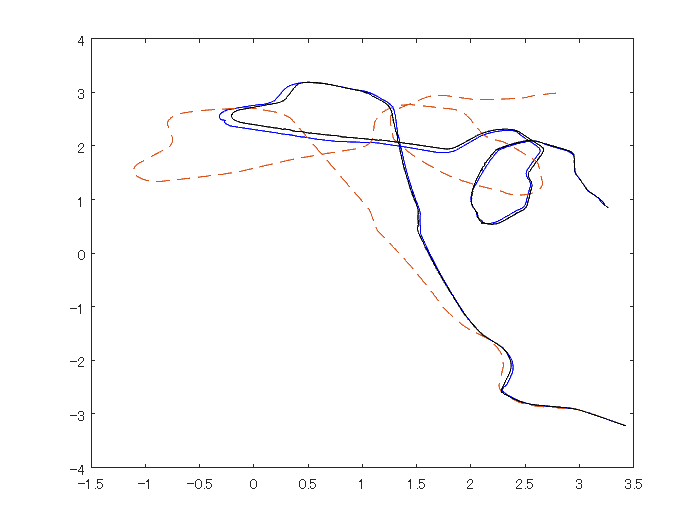

figure()
plot(result(:,1),result(:,2),'b')
hold on
plot(deadReconing(:,1),deadReconing(:,2),"--")
plot(allData.trueX(1:num2),allData.trueY(1:num2),'k')
hold off

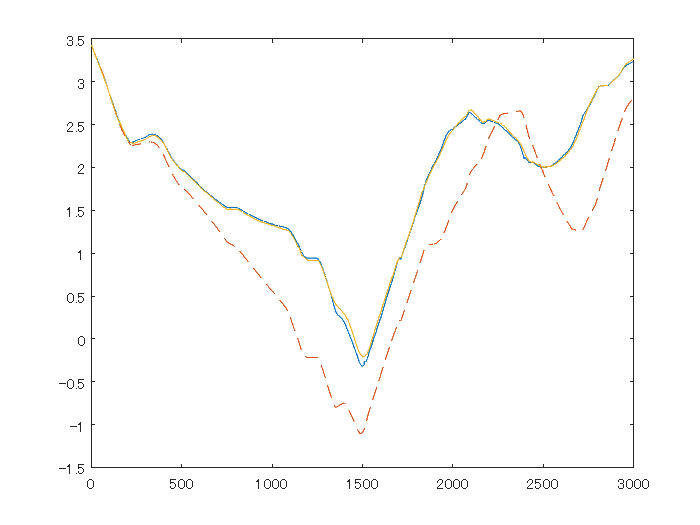

plot(result(:,1))
hold on
plot(deadReconing(:,1),"--")
plot(allData.trueX(1:num2))
hold off

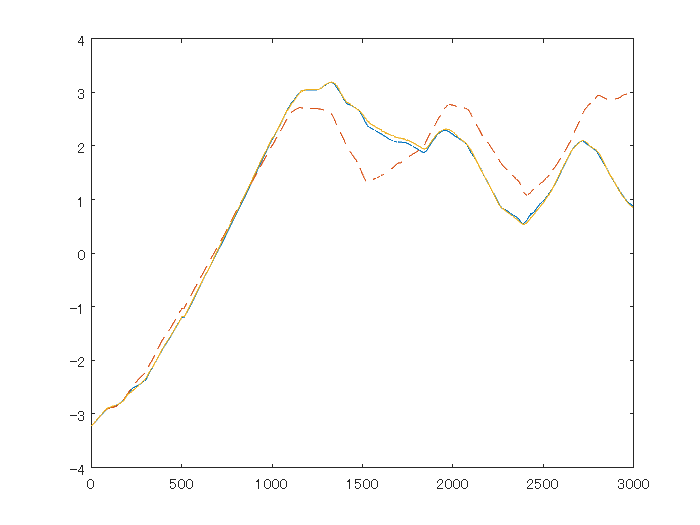


figure()
plot(result(:,2))
hold on
plot(deadReconing(:,2),"--")
plot(allData.trueY(1:num2))
hold off

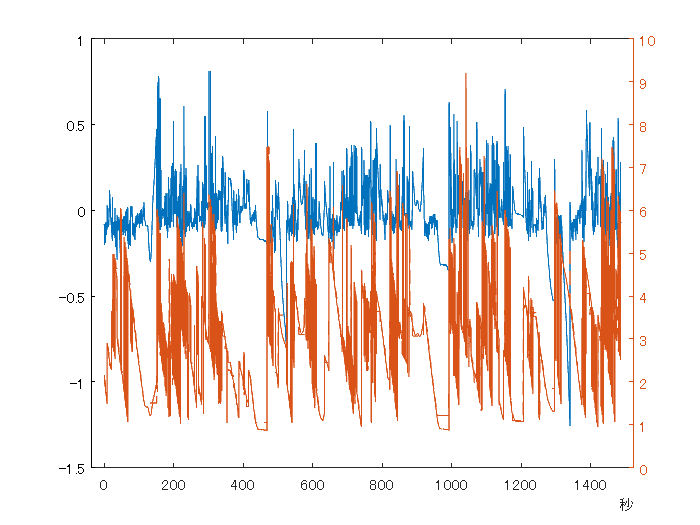

L = sqrt((allData.trueX-allData.poleX).^2+(allData.trueY-allData.poleY).^2);
plot(allData.Time,L-allData.range)
yyaxis right
plot(allData.Time,L,allData.Time,allData.range)